% save_nirfast_data.m
clear all
% In this example, we will use a 2D case to demonstrate how we can generate
% simulated forward data, and use tomographic recontruction from these data
% to recover location of anamalies

## Load the 2D single wavelength mesh

This mesh is 43 mm in diameter and has 16 source/detectors on the periphery

mesh = load_mesh('breast_mesh')

Moving Sources
Moving Detectors


mesh = struct with fields:
            name: 'breast_mesh'
           nodes: [5133×3 double]
          bndvtx: [5133×1 double]
            type: 'stnd'
             mua: [5133×1 double]
           kappa: [5133×1 double]
              ri: [5133×1 double]
             mus: [5133×1 double]
        elements: [10013×3 double]
       dimension: 2
          region: [5133×1 double]
          source: [1×1 struct]
            meas: [1×1 struct]
            link: [240×3 double]
               c: [5133×1 double]
             ksi: [5133×1 double]
    element_area: [10013×1 double]
         support: [5133×1 double]


mesh.mua(:) = 0.01;
mesh.mus(:) = 1;
mesh.kappa(:) = 1./(3.*(mesh.mua+mesh.mus));
mesh.region(:) = 0;

## Set anomaly size and properties

Anomaly 1

blob_a.x=-12; % x location
blob_a.y=7; % y location
blob_a.r=7.5; % radius of blob
blob_a.mua=0.02; % mua set 3 x background
blob_a.mus=1; % mus set same as background
blob_a.region=1;

blob2_a.x=21; % x location
blob2_a.y=21; % y location
blob2_a.r=7.5; % radius of blob
blob2_a.mua=0.02; % mua set 3 x background
blob2_a.mus=1; % mus set same as background
blob2_a.region=1;

blob3_a.x=7; % x location
blob3_a.y=-30; % y location
blob3_a.r=7.5; % radius of blob
blob3_a.mua=0.02; % mua set 3 x background
blob3_a.mus=1; % mus set same as background
blob3_a.region=1; 

mesh_anom = add_blob(mesh,blob_a);

Number of nodes modified = 138


mesh_anom = add_blob(mesh_anom, blob2_a);

Number of nodes modified = 138


mesh_anom = add_blob(mesh_anom, blob3_a);

Number of nodes modified = 141



% Anomaly 2
blob_s.x=-10; % x location
blob_s.y=21; % y location
blob_s.r=7.5; % radius of blob
blob_s.mua=0.01; % mua set same background
blob_s.mus=2; % mus set 3 x background
blob_s.region=2;

blob2_s.x=26; % x location
blob2_s.y=-3; % y location
blob2_s.r=7.5; % radius of blob
blob2_s.mua=0.01; % mua set same background
blob2_s.mus=2; % mus set 3 x background
blob2_s.region=2;

blob3_s.x=-14; % x location
blob3_s.y=-6; % y location
blob3_s.r=7.5; % radius of blob
blob3_s.mua=0.01; % mua set same background
blob3_s.mus=2; % mus set 3 x background
blob3_s.region=2;

mesh_anom = add_blob(mesh_anom,blob_s);

Number of nodes modified = 141


mesh_anom = add_blob(mesh_anom, blob2_s);

Number of nodes modified = 136


mesh_anom = add_blob(mesh_anom, blob3_s);

Number of nodes modified = 138


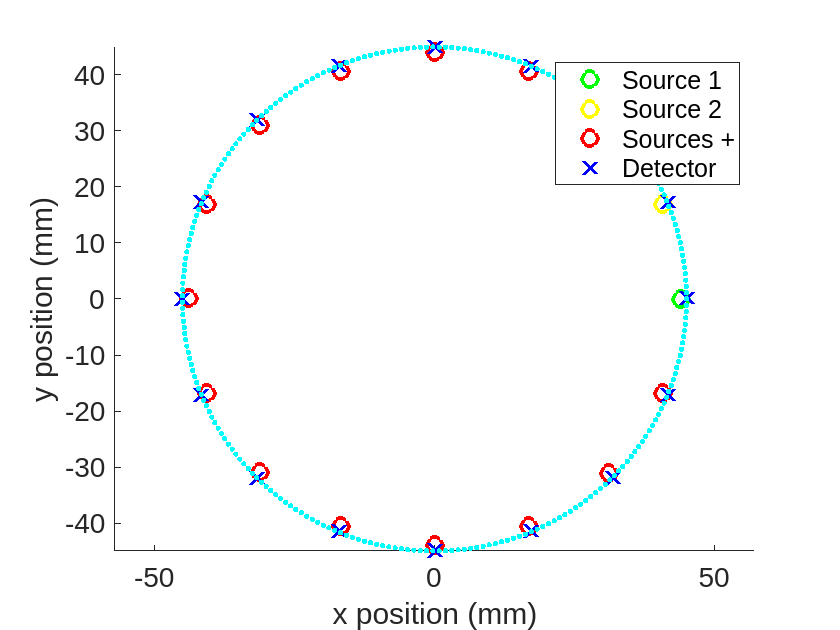

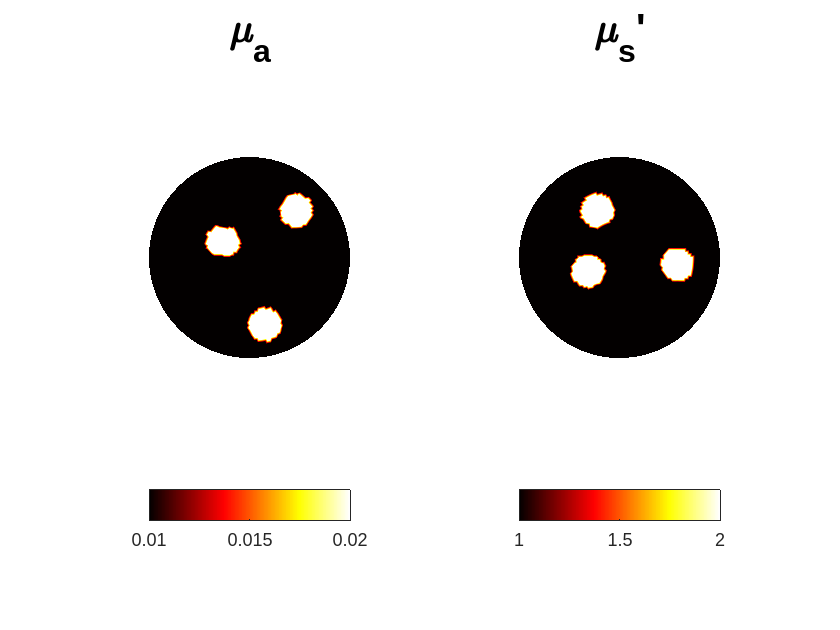


% And view the mesh
plotmesh(mesh_anom,1);

## Generate forward data using Frequency Domain model at 100 MHz

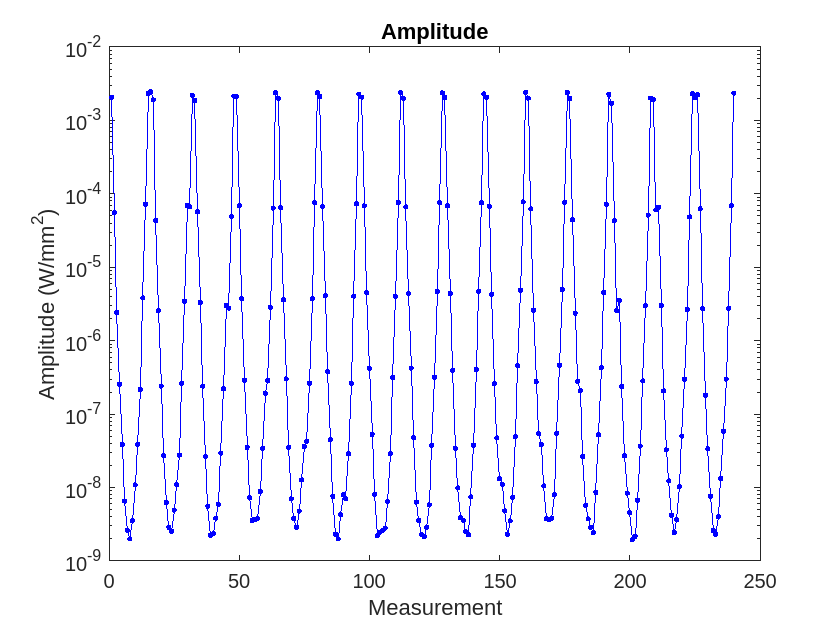

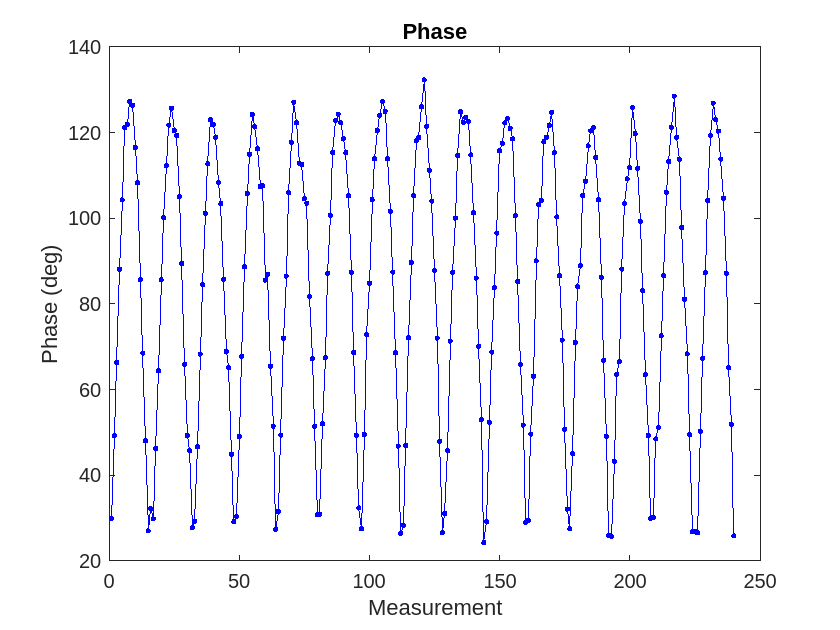

data_anom = femdata(mesh_anom,100);
% and add random noise (1% amplitude, and 2 degrees in Phase)
data_anom_noise = add_noise(data_anom,1,2);
% and view data
plot_data(data_anom_noise);

## Reconstruction

lambda.type='Automatic';
lambda.value=1;
[mesh_recon,pj] = reconstruct(mesh,[30 30],100,data_anom,40,lambda,'standard',0);

Creating coarse mesh
Coarse mesh created with 648 nodes
---------------------------------
Iteration Number          = 1
Projection error          = 137.4182
Amp Regularization        = 0.52731
Phs Regularization        = 0.012296
---------------------------------
Iteration Number          = 2
Projection error          = 4.8479
Projection error change   = 96.4722%
Amp Regularization        = 0.64725
Phs Regularization        = 0.015757
---------------------------------
Iteration Number          = 3
Projection error          = 0.51499
Projection error change   = 89.377%
Amp Regularization        = 0.65262
Phs Regularization        = 0.014453
---------------------------------
Iteration Number          = 4
Projection error          = 0.24285
Projection error change   = 52.843%
Amp Regularization        = 0.65369
Phs Regularization        = 0.014334
---------------------------------
Iteration Number          = 5
Projection error          = 0.16827
Projection error change   = 30.7103%
Amp Re

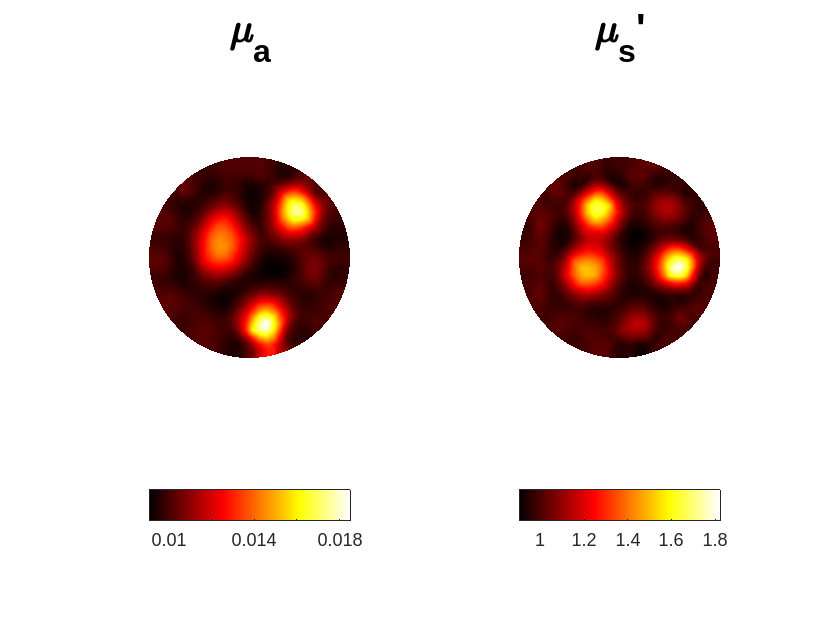

plotmesh(mesh_recon);